# 連続確率変数Continuous Random Variables

***Author****: Ward Nickle, Humboldt State University*

## 背景

離散的な確率変数とその確率分布を理解するために、よくコイン、サイコロ、トランプなどが使われます。例えば，コインを2回投げて表が出るかどうかを考える場合，可能なケースは決まっており，それぞれの確率も決まっています。

一方、連続的確率変数は、無限の値をとることができます。コンピュータを起動するのにかかる時間や、ランダムに選んだ地点での水域の深さなどが例として挙げられます。これらの変数の値は、測定（数えるのではなく）によって得られます。そのため、連続的な確率変数が一つの値をとると考えることは有用ではありませんが、そのような変数がある区間内の値をとる確率を考えることは非常に有用です。

## 一様分布（Uniform Distribution）

一様確率変数とは、すべての値が同じ確率で得られる確率変数です。この性質により、分布の形は長方形になっています。分布の形を表す2つのパラメータ、*a*（確率変数の最小値）と*b*（確率変数の最大値）があります。したがって，a と b の平均，つまり中点をもとに平均値を決めることができます。


$$\mu =\frac{a+b}{2}$$


一様分布の標準偏差は、次の式で与えられます。


$$\sigma =\sqrt{\frac{{\left(b-a\right)}^2 }{12}}$$


同様に、確率変数の取る確率は、長方形の面積の公式、分布の範囲、総面積が1であることを用いて求めることができます。長方形の底辺が範囲$b-a$であり、面積が1であることから、高さは$\frac{1}{b-a}$となります。連続確率変数の場合、確率は確率分布が形成する曲線の下の面積に等しくなります。

確率変数は連続なので、無限に多くの値をとることができます。xが特定の値である確率は0です。理由はこの領域は幅を持たず、一次元であり、面積がないからです。代わりにxが、2つの値、$x_1$と$x_2$の間に存在する確率を考え、対応する長方形の面積を求めます。すると、確率は次の式で与えられます。


$$P\left(x_1 <X<x_2 \right)=\mathrm{base}*\mathrm{height}=\left(x_2 -x_1 \right)\frac{1}{b-a}$$


**例題：**

地元の銀行でサービスを受けるための待ち時間が4分から10分の間で一様に分布しているとします。顧客が6分未満でサービスを受ける確率はどのくらいでしょうか？すべての連続確率変数と同様に、累積密度、つまり、確率変数がある範囲の値になる確率に興味があります。そこで、連続一様累積分布関数を使用します。 [p = unifcdf(x,a,b)](https://www.mathworks.com/help/stats/unifcdf.html). 

unifcdf(6,4,10)

ans = 0.3333

お客様が5分以上待たされる可能性はどのくらいですか？$P\left(X>5\right)=1-P\left(X<5\right)$という*補数規則*を用いましょう。

1-unifcdf(5,4,10)

ans = 0.8333

代わりに、cdfのupper引数を使うこともできます。

unifcdf(5,4,10,'upper')

ans = 0.8333

**課題：**

ヘルパー関数 `plotUniformDist` は，一様乱数の確率密度関数（pdf）を描画して$P\left(x_1 <X<x_2 \right)$を表示します。*x, *a ,b は実数でかつ$a<b$でなければなりません。$x_1 <x_2$であるx1, x2の間に、 x の値が存在する確率を計算します。

上記の例を満たすような適切な値を、下の各テキストボックスに入力してください。 **Run** ボタンをクリックすると、解答が可視化されます。

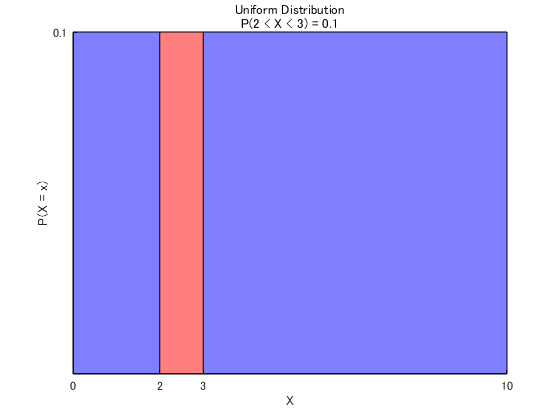

 
a = 0; % min of distribution
b = 0; % max of distribution
x1 = 0; % min of interval
x2 = 0; % max of interval
plotUniformDist(a,b,x1,x2)

## 正規分布（Normal Distribution）

連続確率変数の最も一般的な分布は正規分布で、多くの特徴的な性質を持っています。正規分布は釣鐘型で、対称性を持ち、裾がx軸に漸近的に近づきます。対称性のため平均値と中央値は等しく、分布の中心となります。釣鐘のように平均値から離れるにつれて、分布の高さが小さくなり、これらの値は平均値よりも少ないことを意味します。最後に、正規分布は漸近的であるため、平均から十分に離れると、曲線の高さは0に近づきます。正規分布を完全に記述する2つのパラメータがあります。それは平均$\mu$、および標準偏差$\sigma$であり、正規分布は次の式で与えられます。


$$P\left(x\right)=\frac{1}{\sigma \sqrt{2\pi }}e^{-\left\lbrack \frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }\right\rbrack }$$


**例題：**

最近の米国農務省の報告書によると、平均的な4人家族の食費は週当たり平均218ドルで、標準偏差は24ドルです。食費が正規分布していると仮定した場合、4人家族のうち、週当たり250ドル以上の食費を使っている家庭は何％でしょうか？ここでは正規累積分布関数[`p = normcdf(x,mu,sigma)`](https://www.mathworks.com/help/stats/normcdf.html#d120e513735)を用いて解きます。`上記のように、私たちは`上側`の確率に興味があるので、下側の補数を使用することができます。`

1-normcdf(250,218,24)

ans = 0.0912

繰り返しになりますが、これはupper引数を使用するのと同等です。

normcdf(250,218,24,'upper')

ans = 0.0912

99パーセンタイルの家族が使う金額に興味があるとします。つまり、下側の確率が0.99になるようなxの値です。これは逆正規累積分布関数[`x = norminv(p,mu,sigma)`](https://www.mathworks.com/help/stats/norminv.html#d120e515658)を使って求められます。`逆関数は定義域と値域が入れ替わる、すなわち、pが与えられた場合のxの値に興味がある場合には、本質的に逆になることに注意しましょう。`

norminv(0.99,218,24)

ans = 273.8323

**課題：**

ヘルパー関数 `plotNormalDist` は，正規確率変数の確率密度関数 (pdf) を描画し$P\left(x_1 <X<x_2 \right)$ を表示します． `mu` は任意の実数ですが，`sigma` は非負でなければなりません．$x_1 <x_2$であるx1から x2の間に、 x の値が存在する確率を示しています。

上記の例を満たすような適切な値を、下の各テキストボックスに入力してください。 **Run** ボタンをクリックすると、解答が可視化されます。

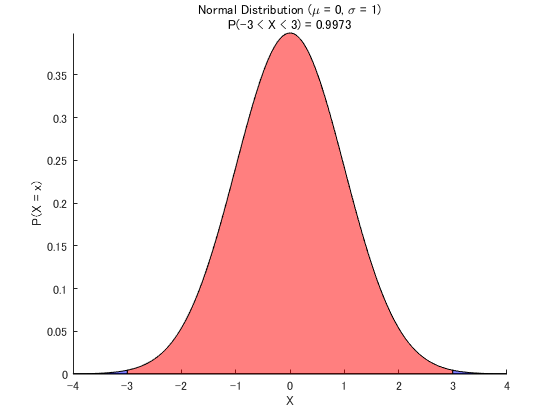

 
mu = 0; % mean of distribution
sd = 0; % sd of distribution
x1 = 0; % min of interval
x2 = 0; % max of interval
plotNormalDist(mu,sd,x1,x2)

## 標準正規分布（Standard Normal Distribution）

様々な正規分布が存在するので、一貫した視点を提供するために正規分布を標準化したいと思うかもしれません。これが、標準正規分布の動機です。標準正規分布の平均は0で、標準偏差は1です。正規確率変数を標準正規変数に変換するには、zスコア（z値と呼ばれることもあります）を計算します。


$$z=\frac{x-\mu }{\sigma }$$


zスコアとは、xの平均値からのずれが、標準偏差の何倍離れているか示す数です。負のZスコアは、xの値が平均を下回ることを表し、正のZスコアは、xの値が平均を上回ることを表します。Zスコアは、正規確率変数の値を見るための標準的な方法です。観測値の約68%が平均から1標準偏差内にあり、95%が平均から2標準偏差内にあるという経験則を使用すると、特定のZスコアに関連する尤度をすぐに推測することができます。

**例題：**

妊娠期間が252日から298日までのものを臨月とする。妊娠が平均272日、標準偏差9日で正規分布している場合、臨月の割合はどのくらいでしょうか？252日と298日のZスコアは何ですか？計算のために、変数を標準化する必要はありませんが、標準化すれば、値が平均から何シグマ離れているかを知ることができます。Zスコアは、以下のように求めることができます。

z1 = (252-272)/9

z1 = -2.2222

z2 = (298-272)/9

z2 = 2.8889

確率は [`p = normcdf(x)`](https://www.mathworks.com/help/stats/normcdf.html?s_tid=srchtitle#d120e513700)` を用いて計算しますが、この関数は、平均0,標準偏差1の標準正規分布を仮定します。この関数は入力の` (-∞,x] の範囲で確率を`計算するので、`$P\left(z_1 <Z<z_2 \right)=P\left(Z<z_2 \right)-P\left(Z<z_1 \right)$.のように計算する必要があります。

normcdf(z2)-normcdf(z1)

ans = 0.9849

**課題：**

ヘルパー関数 `plotNormalDist` は，標準正規確率変数の確率密度関数 (pdf) を描画して、$P\left(x_1 <X<x_2 \right)$を表示します．$x_1 <x_2$であるx1から x2の間にある x の値に対する確率を表示します。

上記の例を満たすような適切な値を、下の各テキストボックスに入力してください。 **Run** ボタンをクリックすると、解答が可視化されます。

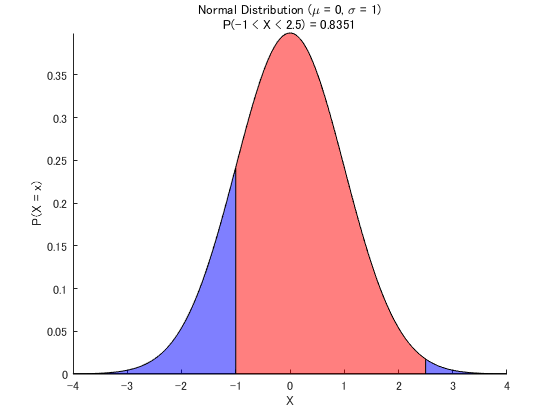

 
mu = 0; % mean of distribution
sd = 1; % sd of distribution
x1 = 0; % min of interval
x2 = 0; % max of interval
plotNormalDist(mu,sd,x1,x2)

## 指数分布（Exponential Distribution）

指数分布は、連続して発生する事象の間の時間を求めるために使用されます。事象は独立しており、一定の割合で発生すると考えられます。指数分布は正に歪んでおり、1つのパラメータ $\lambda$ (lambda)で定義されています。$\lambda$は単位時間当たりの事象頻度を示し、$\frac{1}{\mu }$（$\mu$: 平均到着時間）とイコールです。確率は以下のいずれかで与えられます。


$$P\left(x\right)=\frac{1}{\mu }e^{\frac{-x}{\mu }} =\lambda e^{-\lambda x}$$


**例題：**

コンピュータの起動にかかる時間が、平均27秒の指数分布に従うとします。コンピュータが15秒以下で起動する確率は何パーセントでしょうか？指数累積密度関数を使ってみましょう。[`p = expcdf(x,mu)`](https://www.mathworks.com/help/stats/expcdf.html#d120e235154).

expcdf(15,27)

コンピュータの起動に30秒から45秒かかる可能性はどのくらいでしょうか？ここでは、$P\left(30<X<45\right)=P\left(X<45\right)-P\left(X<30\right)$であるので、起動時間が45秒未満である確率と、30秒未満である確率の差を求めます。

expcdf(45,27)-expcdf(30,27)

**課題：**

ヘルパー関数 `plotExpDist` は，指数確率変数の確率密度関数（pdf）を描画し、$P\left(x_1 <X<x_2 \right)$を表示します。x1から x2の間に、 x の値が存在する確率を表示します。

上記の例を満たすような適切な値を、下の各テキストボックスに入力してください。 **Run** ボタンをクリックすると、解答が可視化されます。

  
mu = 0; % mean arrival time
x1 = 0; % min of interval
x2 = 0; % max of interval
plotExpDist(mu,x1,x2)

## ヘルパー関数（Helper Functions）

これらの関数は、このスクリプトで説明されている様々な分布を、定義されたパラメータと値の区間を与えてプロットします。

function plotUniformDist(a,b,x1,x2)
    % a min of distribution
    % b max of distribution
    % x1 min of interval
    % x2 max of interval
    
    close all
    
    h = 1/(b-a);
    figure
    hold on
    
    x = [a,x1,x1,a];
    y = [0,0,h,h];
    fill(x,y,'b','FaceAlpha','0.5')
    
    x = [x1,x2,x2,x1];
    y = [0,0,h,h];
    fill(x,y,'r','FaceAlpha','0.5')
    
    x = [x2,b,b,x2];
    y = [0,0,h,h];
    fill(x,y,'b','FaceAlpha','0.5')
    
    p = round((x2-x1)*h,4);
    
    xticks(unique([a,b,x1,x2]))
    yticks(round(h,2))
    title({'Uniform Distribution',['P(',num2str(x1),' < X < ',num2str(x2),') = ',num2str(p)]})
    xlabel('X')
    ylabel('P(X = x)')
    
    hold off
    
end

function plotNormalDist(mu,sigma,x1,x2)
    % mu is the mean of the distribution
    % sigma is the standard deviation of the distribution
    % x1 min of interval
    % x2 max of interval
    
    close all
    
    l = mu-4*sigma;
    r = mu+4*sigma;
    x = unique([(l:0.01:r),x1,x2]);
    y = normpdf(x,mu,sigma);
    p = round(normcdf(x2,mu,sigma)-normcdf(x1,mu,sigma),4);
    
    figure
    hold on
    
    left = find(x<=x1);
    middle = find(x>=x1 & x<=x2);
    right = find(x>=x2);
    fill([x(left),fliplr(x(left))],[zeros(1,numel(left)),fliplr(y(left))],'b','FaceAlpha','0.5')
    fill([x(middle),fliplr(x(middle))],[zeros(1,numel(middle)),fliplr(y(middle))],'r','FaceAlpha','0.5')
    fill([x(right),fliplr(x(right))],[zeros(1,numel(right)),fliplr(y(right))],'b','FaceAlpha','0.5')
    
    axis([l,r,-inf,inf])
    xticks([l:sigma:r])
    title({['Normal Distribution (\mu = ',num2str(mu),', \sigma = ',num2str(sigma),')'],['P(',num2str(x1),' < X < ',num2str(x2),') = ',num2str(p)]})
    xlabel('X')
    ylabel('P(X = x)')
    
    hold off
    
end

function plotExpDist(mu,x1,x2)
    % mu is the mean number of success per interval
    % x1 min of interval
    % x2 max of interval
    
    close all
    l=0;
    r=round(expinv(0.995,mu));
    
    res = 0.1;
    x = unique([(l:res:r),x1,x2]);
    y = exppdf(x,mu);
    p = round(expcdf(x2,mu)-expcdf(x1,mu),4);
    
    figure
    hold on
    
    left = find(x<=x1);
    middle = find(x>=x1 & x<=x2);
    right = find(x>=x2);
    fill([x(left),fliplr(x(left))],[zeros(1,numel(left)),fliplr(y(left))],'b','FaceAlpha','0.5')
    fill([x(middle),fliplr(x(middle))],[zeros(1,numel(middle)),fliplr(y(middle))],'r','FaceAlpha','0.5')
    fill([x(right),fliplr(x(right))],[zeros(1,numel(right)),fliplr(y(right))],'b','FaceAlpha','0.5')
    
    axis([l,r,-inf,inf])
    title({['Exponential Distribution (\lambda = ',num2str(round(1/mu,4)),')'],['P(',num2str(x1),' < X < ',num2str(x2),') = ',num2str(p)]})
    xlabel('X')
    ylabel('P(X = x)')
    
    hold off
    
end